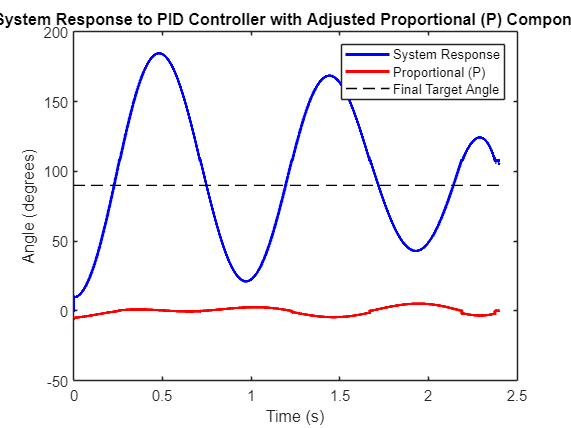

% Define constants
Kp = 0.15;  % Proportional gain
Ki = 0.01;  % Integral gain
Kd = 0.1;   % Derivative gain
Ko = 0.05;  % Overshoot correction gain
Ts = 1/4096; % Sampling time for the gyroscope (12-bit resolution)

% Target angle
initial_target_angle_deg = 90;
final_target_angle_deg = 90;
overshoot_factor = 1.2; % Adjust overshoot factor as needed
overshoot_target_angle_deg = final_target_angle_deg * overshoot_factor;

% Time vector
t = 0:Ts:(overshoot_target_angle_deg/45); % Simulation time (ensure it passes overshoot target angle)

% System response
response = zeros(size(t));

% Individual contributions
P_contributions = zeros(size(t));
I_contributions = zeros(size(t));
D_contributions = zeros(size(t));

% Initial conditions
current_angle = 0; % Start at 0 degrees
error_accumulator = 0; % Initialize error accumulator for the integral component
prev_error = 0; % Initialize previous error for the derivative component

% Simulate system response to PID controller
for i = 1:length(t)
    % Calculate error
    if current_angle < overshoot_target_angle_deg
        error = overshoot_target_angle_deg - current_angle;
    else
        error = final_target_angle_deg - current_angle;
    end
    
    % Integral response
    error_accumulator = error_accumulator + error;
    I_term = Ki * error_accumulator;
    
    % Derivative response
    D_term = Kd * (error - prev_error) / Ts;
    prev_error = error;
    
    % Proportional response with logarithmic increase
    P_term = Kp * error * log(1 + i/length(t) * (exp(1) - 1));
    if P_term > 0
        P_term = P_term - Ko * abs(error); % Decrease proportional term if overshoot
    else
        P_term = P_term + Ko * abs(error); % Increase proportional term if overshoot
    end
    
    % Calculate control signal
    u = P_term + I_term + D_term;
    
    % Update system response
    response(i) = current_angle;
    current_angle = current_angle + u * Ts; % Update angle using Euler integration
    
    % Gradually reduce target angle after overshooting
    if current_angle > overshoot_target_angle_deg
        current_angle = current_angle - (current_angle - final_target_angle_deg) * Ts / (max(t) - t(i));
    end
    
    % Store individual contributions
    P_contributions(i) = P_term;
    I_contributions(i) = I_term;
    D_contributions(i) = D_term;
end

% Plot system response with P component
figure;
plot(t, response, 'b', t, P_contributions, 'r', 'LineWidth', 2);
hold on;
plot([0, max(t)], [final_target_angle_deg, final_target_angle_deg], 'k--'); % Plot final target angle
hold off;
xlabel('Time (s)');
ylabel('Angle (degrees)');
title('System Response to PID Controller with Adjusted Proportional (P) Component');
legend('System Response', 'Proportional (P)', 'Final Target Angle');

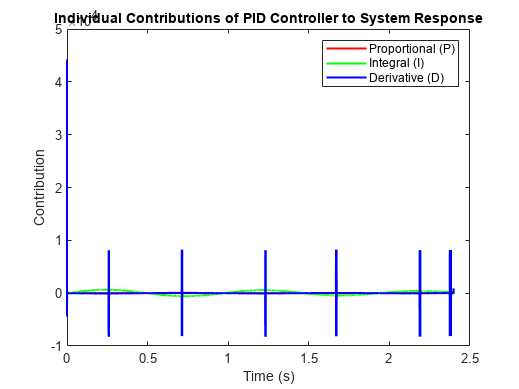


% Plot individual contributions
figure;
plot(t, P_contributions, 'r', t, I_contributions, 'g', t, D_contributions, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Contribution');
title('Individual Contributions of PID Controller to System Response');
legend('Proportional (P)', 'Integral (I)', 'Derivative (D)');